# Introduction to Drones - 22AIE448

**3D Mapping using a Monocular Camera and Control by Visual-Inertial Odometry (VIO)**

Group CD2 : Ravishanmugam K, Ishwarya Murugesan, Aparna Bharani, Cibikumar B, Akhilan S

School of Artificial Intelligence, Amrita Vishwa Vidyapeetham

**Toy model 3 - Model 2, Part 3 : control with limits - MPC, QP, receding horizon, apply to the drone (blocks 7 to 10)**

Run M2_1 and M2_2 first (they create `dmdc_model.mat`).

clearvars
clear all
ready = true;
PUBLISH = not(ready);   % make this PUBLISH = ready; to export the file as PDF

clearvars -except PUBLISH ready

## Block 7 - Model Predictive Control

LQR has no limits. A real drone has: thrust between 5 and 25 N, `max_velocity` = 1 m/s, a maximum tilt for the camera. MPC plans only $N$ steps ahead and writes the limits into the problem:


$$\min_{u_0,\dots,u_{N-1}} \sum_{k=0}^{N-1}\left(x_k^T Q x_k + u_k^T R u_k\right) + x_N^T P_f\,x_N$$



$$\textrm{subject to } x_{k+1} = Ax_k + Bu_k, \quad x_0 = \textrm{measured state}, \quad u_{min} \le u_k \le u_{max}, \quad |Cx_k| \le x_{max} \qquad \rightarrow (M2.12)$$


**Why the terminal weight is the DARE matrix,** $P_f = P$: $x_N^TPx_N$ is exactly the cost of the rest of the flight when no limit is active after step $N$. So when no limit is active, MPC gives **exactly** the LQR answer.

## Block 8 - Quadratic Program

**Prediction.** Apply the model again and again: $x_1 = Ax_0 + Bu_0$, $x_2 = A^2x_0 + ABu_0 + Bu_1$, ...


$$\mathbf{X} = S_x x_0 + S_u \mathbf{U}, \quad S_x = \left[\begin{array}{c} A\\ A^2\\ \vdots\\ A^N \end{array}\right], \quad S_u = \left[\begin{array}{cccc} B & 0 & \cdots & 0\\ AB & B & \cdots & 0\\ \vdots & & \ddots & \vdots\\ A^{N-1}B & \cdots & AB & B \end{array}\right] \qquad \rightarrow (M2.13)$$


**Cost.** Substitute $\mathbf{X}$ and drop the part that does not depend on $\mathbf{U}$:


$$\min_{\mathbf{U}} \frac{1}{2}\mathbf{U}^T H\mathbf{U} + f^T\mathbf{U}, \qquad H = 2\left(S_u^T\bar{Q}S_u + \bar{R}\right), \qquad f = 2S_u^T\bar{Q}S_x x_0 \qquad \rightarrow (M2.14)$$



$$\textrm{s.t.}\quad G\,\mathbf{U} \le h, \qquad A_{eq}\mathbf{U} = b_{eq} \qquad \rightarrow (M2.15)$$


with $\bar{Q} = \textrm{diag}(Q,\dots,Q,P_f)$, $\bar{R} = \textrm{diag}(R,\dots,R)$. $H$ is positive definite: a bowl with one bottom inside a fence, so the answer is unique.

**Toy example by hand.** $a = 1.1$, $b = 0.5$, $q = r = 1$, $N = 2$, $P_f = 3.1215$, $x_0 = 1$:


$$S_x = \left[\begin{array}{c} 1.1\\ 1.21 \end{array}\right], \quad S_u = \left[\begin{array}{cc} 0.5 & 0\\ 0.55 & 0.5 \end{array}\right], \quad H = \left[\begin{array}{cc} 4.3885 & 1.7168\\ 1.7168 & 3.5607 \end{array}\right], \quad f = \left[\begin{array}{c} 5.2547\\ 3.7770 \end{array}\right]$$


a = 1.1;  b = 0.5;  Pf = 3.12146;  x0 = 1;
Sx = [a; a^2];
Su = [b 0; a*b b];
Qbar = diag([1 Pf]);  Rbar = eye(2);
H = 2*(Su'*Qbar*Su + Rbar)

H =     4.3885    1.7168
    1.7168    3.5607


f = 2*Su'*Qbar*Sx*x0

f =     5.2547
    3.7770


**(i) No limits:** $\mathbf{U}^* = -H^{-1}f$. The first move equals the LQR move $-Kx_0 = -0.9643$.

U_free = (-H\f)'

U_free =    -0.9643   -0.5958


**(ii) With limits**, $|u_k| \le 0.5$: both moves sit on the limit.

G = [eye(2); -eye(2)];  h = 0.5*ones(4,1);
U_limited = DroneLib.qp(H, f, G, h)'

U_limited =    -0.5000   -0.5000


**(iii) With an equality** that forces $x_2 = 0$: $[0.55\ \ 0.5]\,\mathbf{U} = -1.21$.

U_equality = DroneLib.qp(H, f, zeros(0,2), zeros(0,1), [a*b b], -a^2)'

U_equality =    -1.3057   -0.9837


check_x2 = a^2*x0 + [a*b b]*U_equality'

check_x2 = 0

## The drone MPC problem

$N = 25$ (1 s look-ahead), $5 \le T \le 25$ N, $|\tau_{x,y}| \le 0.3$ N m, $|\tau_z| \le 0.05$ N m, $|v_i| \le 1$ m/s (`max_velocity`) and roll, pitch $\le 20^\circ$.

clearvars -except PUBLISH ready
load('dmdc_model.mat');           % A, B (learned), P (drone), P_dare, K, Q, R, dt, nSub, u_trim
N = 25;
u_min = [5 - P.m*P.g0; -0.3; -0.3; -0.05];
u_max = [25 - P.m*P.g0; 0.3; 0.3; 0.05];
C = zeros(5,12);  C(1,4) = 1; C(2,5) = 1; C(3,6) = 1; C(4,7) = 1; C(5,8) = 1;
x_max = [1; 1; 1; 0.35; 0.35];
mpc = DroneLib.mpc_build(A, B, Q, R, P_dare, N, u_min, u_max, C, x_max);
decision_variables = size(mpc.H, 1)

decision_variables = 100

inequality_constraints = size(mpc.G, 1)

inequality_constraints = 450

**Small offset (5 cm): no limit is active, so MPC = LQR.**

x_small = [0.05; -0.05; 0.05; zeros(9,1)];
u_mpc = DroneLib.mpc_solve(mpc, x_small)'

u_mpc =    -0.4557   -0.0138   -0.0137   -0.0004


u_lqr = (-K*x_small)'

u_lqr =    -0.4557   -0.0138   -0.0137   -0.0004


**Large offset (2 m): LQR would ask for more than allowed, MPC respects every limit.**

x_big = [0; 0; -2; zeros(9,1)];
u_lqr_big = (-K*x_big)'

u_lqr_big =    18.0771   -0.0007   -0.0015    0.0082


[u_mpc_big, U] = DroneLib.mpc_solve(mpc, x_big);
u_mpc_big = u_mpc_big'

u_mpc_big =    10.2850   -0.0018   -0.0002    0.0172


X_plan = reshape(mpc.Sx*x_big + mpc.Su*U, 12, N);
planned_max_vz = max(abs(X_plan(6,:)))

planned_max_vz = 1.0000

## Block 9 - Receding horizon


$$\mathbf{U}^*(x_k) = [u_0^*,\ u_1^*,\ \dots,\ u_{N-1}^*] \quad \Rightarrow \quad \textrm{apply only } u_0^*,\ \textrm{measure } x_{k+1},\ \textrm{solve again} \qquad \rightarrow (M2.16)$$


Plan 1 s ahead, act for 40 ms, look again. Re-solving from fresh measurements turns the plan into feedback.

x0 = [1.5; -1.0; -1.2; zeros(9,1)];
Kn = 200;  t = (0:Kn)*dt;
Xm = zeros(12, Kn+1);  Xl = Xm;  Xm(:,1) = x0;  Xl(:,1) = x0;  tsolve = zeros(1,Kn);
for k = 1:Kn
    tic;  um = DroneLib.mpc_solve(mpc, Xm(:,k));  tsolve(k) = toc;
    ul = min(max(-K*Xl(:,k), u_min), u_max);          % LQR, clipped to the same input limits
    Xm(:,k+1) = A*Xm(:,k) + B*um;
    Xl(:,k+1) = A*Xl(:,k) + B*ul;
end
max_speed_MPC = max(abs(Xm(4:6,:)), [], 'all')

max_speed_MPC = 1.0000

max_speed_LQR = max(abs(Xl(4:6,:)), [], 'all')

max_speed_LQR = 1.1722

median_solve_time_ms = 1000*median(tsolve)     % budget: 40 ms per sample

median_solve_time_ms = 3.2166

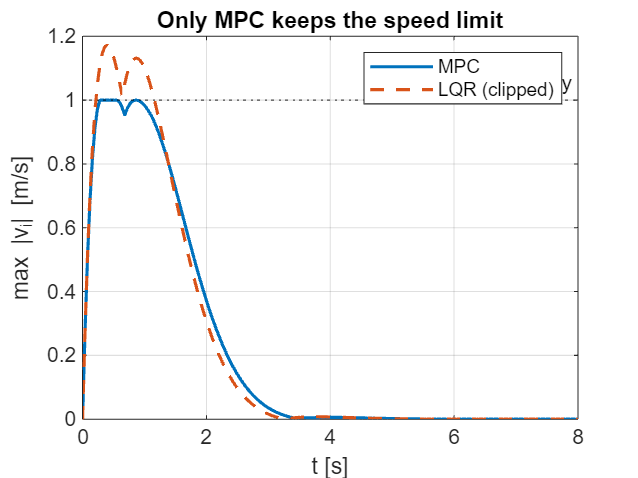

figure
plot(t, max(abs(Xm(4:6,:))), t, max(abs(Xl(4:6,:))), '--', LineWidth=1.5); hold on
yline(1, 'k:', "max\_velocity"); hold off; grid on
xlabel("t [s]"); ylabel("max |v_i| [m/s]"); legend("MPC", "LQR (clipped)")
title("Only MPC keeps the speed limit")

## Block 10 - Apply to the drone

The controllers work with deviations, the motors need absolute values:


$$u_k = u_{trim} + \left\{\begin{array}{ll} u_0^* & \textrm{(MPC)}\\ -Kx_k & \textrm{(LQR)} \end{array}\right. = \left[\begin{array}{c} T_k\\ \tau_k \end{array}\right], \qquad f = \Gamma^{-1}u_k, \qquad \Omega_i = \sqrt{f_i/k_f} \qquad \rightarrow (M2.17, M2.18)$$


**One sample by hand:** the drone is at $[1.5,\,-1.0,\,0.8]$ m, at rest; the target is $[0,0,2]$.

x_world = DroneLib.pack(P.p_hover + [1.5; -1.0; -1.2], zeros(3,1), eye(3), zeros(3,1));
xd = DroneLib.to_dev(x_world, P.p_hover);
du = DroneLib.mpc_solve(mpc, xd);
u  = u_trim + du;
[Omega, f] = DroneLib.mixer(u, P);
u_abs = u'

u_abs =    25.0000   -0.2789   -0.3000    0.0019


f_rotors = f'

f_rotors =     7.1147    5.3271    6.5391    6.0191


Omega_rad_s = Omega'

Omega_rad_s =   912.2875  789.4006  874.6073  839.1083


**The real test:** the **nonlinear** drone with wind and sensor noise, flown by controllers that were designed only on the model learned from data.

figure
rng(10);
Kn = 250;  t = (0:Kn)*dt;  names = ["MPC", "LQR"];
for c = 1:2
    x = x_world;  Xw = zeros(18, Kn+1);  Xw(:,1) = x;  Om = zeros(4, Kn);
    for k = 1:Kn
        % ideal state sensor (true state + noise); M2_4 replaces this line by the EKF of block 11
        xm = DroneLib.to_dev(x, P.p_hover) + [0.01*ones(3,1); 0.02*ones(3,1); 0.005*ones(3,1); 0.01*ones(3,1)].*randn(12,1);
        if c == 1
            du = DroneLib.mpc_solve(mpc, xm);
        else
            du = min(max(-K*xm, u_min), u_max);
        end
        [Om(:,k), ~, u_app] = DroneLib.mixer(u_trim + du, P);
        d = [0.2*randn(3,1); 5e-4*randn(3,1)];
        for j = 1:nSub, x = DroneLib.rk4(x, u_app, dt/nSub, P, d); end
        Xw(:,k+1) = x;
    end
    fprintf("%s : max |v| = %.3f m/s, error at 10 s = %.3f m, motors %.0f - %.0f rad/s\n", names(c), ...
        max(abs(Xw(4:6,:)), [], 'all'), norm(Xw(1:3,end) - P.p_hover), min(Om(:)), max(Om(:)));
    plot3(Xw(1,:), Xw(2,:), Xw(3,:), LineWidth=1.5); hold on

MPC : max |v| = 0.994 m/s, error at 10 s = 0.015 m, motors 584 - 913 rad/s
LQR : max |v| = 1.118 m/s, error at 10 s = 0.031 m, motors 613 - 911 rad/s


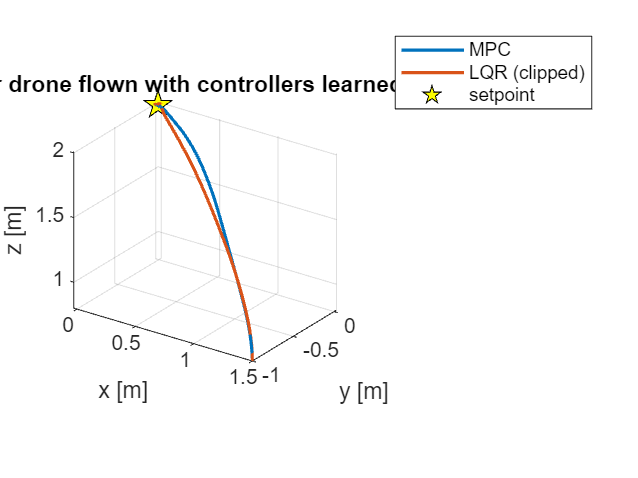

end
plot3(0, 0, 2, 'kp', MarkerSize=14, MarkerFaceColor='y'); hold off
grid on; axis equal; view(35, 25); xlabel("x [m]"); ylabel("y [m]"); zlabel("z [m]")

legend("MPC", "LQR (clipped)", "setpoint"); title("Nonlinear drone flown with controllers learned from data")

**In the real drone:** the measured state $x_k$ comes from an EKF: block 11 (M2_4) builds it from camera pixels and the gyroscope. In today's SITL set-up ArduPilot's EKF3 provides it (`/ap/v1/pose/filtered` and `/ap/v1/twist/filtered`), the command goes through the same motor mixer, and new logs can be fed back into M2_1 to re-learn $A, B$.

if(PUBLISH == ready)
    mlxfile = matlab.desktop.editor.getActive().Filename;
    [folder, name, ext] = fileparts(mlxfile);
    outfilepdf = fullfile(folder, 'pdf', [name, ext, '.pdf']);
    export(mlxfile, outfilepdf);
    if ispc
        winopen(outfilepdf);
    elseif ismac
        system(['open ' char(outfilepdf)]);
    else
        system("env -u LD_LIBRARY_PATH xdg-open '" + outfilepdf + "' &");
    end
end